# *E.coli *(iJO1366) Alanine and Aspartate Metabolism (including Asparagine)

Author: H. Scott Hinton, Utah State University

Reviewer:

## INTRODUCTION

The purpose of this tutorial is to review the basic structure and capabilities of the "Alanine and Aspartate Metabolism" subsystem of the iJO1366* E.coli* model.

## MATERIALS

This tutorial is based on the *Constraint-Based Reconstruction and Analysis* (COBRA) Toolbox [1,2]. To use this tutorial requires the 2016a or newer version of Matlab ([https://www.mathworks.com](https://www.mathworks.com)/) and the COBRA toolbox software that can be downloaded from [https://opencobra.github.io/cobratoolbox/latest/index.html.](https://opencobra.github.io/cobratoolbox/latest/index.html.) The installation instructions and troubleshooting tips are also available on this website.

## **EQUIPMENT SETUP**

Initalize the COBRA toolbox.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  (not installed).
 > Checking if remote can be reached ...  (unsuccessful - no internet connection).
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.


 > Try running
   >> TranslateSBML('C:\Users\hinton\cobratoolbox\test\models\Ec_iAF1260_flux1.xml');
   in order to debug.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [-*--] GUROBI_PATH: C:\gurobi702\win64\matlab
   - [----] TOMLAB_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ... Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver int

Select the optimizer solver.

% changeCobraSolver('glpk','all');
changeCobraSolver('gurobi7','all');

 > CBT_LP_SOLVER has been set to gurobi.
 > CBT_MILP_SOLVER has been set to gurobi.
 > CBT_QP_SOLVER has been set to gurobi.
 > CBT_MIQP_SOLVER has been set to gurobi.
 > CBT_NLP_SOLVER has been set to gurobi.


% changeCobraSolver('tomlab_cplex','all');
% changeCobraSolver('gurobi6','all');

Load the *E.coli *iJO1366 model.

load('iJO1366.mat');
saved_model = iJO1366;
model = saved_model;

## PROCEDURE

## **1.  Alanine, Aspartate and Asparagine Metabolism**

The purpose of this tutorial is to identify and review the structure and capabilities of the "Alanine and Aspartate Metabolism" subsystem of the *E.coli* iJO1366 model. This will begin with an overview of the complete subsystem. This overview will be followed by more detailed descriptions of the individaul L-alanine, L-aspartate and L-asparagine biosynthesis pathways. It will conclude with a simulation that shows the maximum flux that each these amino acids can produce in an oxidative range from anaerobic to aerobic conditions.

## **2. "Alanine and Aspartate Metabolism" Subsystem**

The reactions associated with the "Alanine and Aspartate Metabolism" subsystem can be extracted from the model as shown below.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
alanineAspartateSubSystems = {'Alanine and Aspartate Metabolism'};
alanineAspartateReactions = model.rxns(ismember(model.subSystems,alanineAspartateSubSystems));
[tmp,alanineAspartate_rxnID] = ismember(alanineAspartateReactions,model.rxns);
reactionNames = model.rxnNames(alanineAspartate_rxnID);
reactionFormulas = printRxnFormula(model,alanineAspartateReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',alanineAspartateReactions)

T = 9×2 table
                               reactionNames                                                      reactionFormulas                                  
               _____________________________________________    ____________________________________________________________________________________

    ALAR       'Alanine racemase'                               'ala__L_c  <=> ala__D_c '                                                           
    ALATA_L    'L-alanine transaminase'                         'akg_c + ala__L_c  <=> glu__L_c + pyr_c '                                           
    ASNN       'L-asparaginase'                                 'asn__L_c + h2o_c  -> asp__L_c + nh4_c '                                            
    ASNNpp     'L-asparaginase'                                 'asn__L_p + h2o_p  -> asp__L_p + nh4_p '

The connectivity between these reactions can be visualized through an Escher [3] map of this  "Alanine and Aspartate Metabolism" subsystem as shown below (Alanine_Asprartate_Metaboism_Subsystem.json).

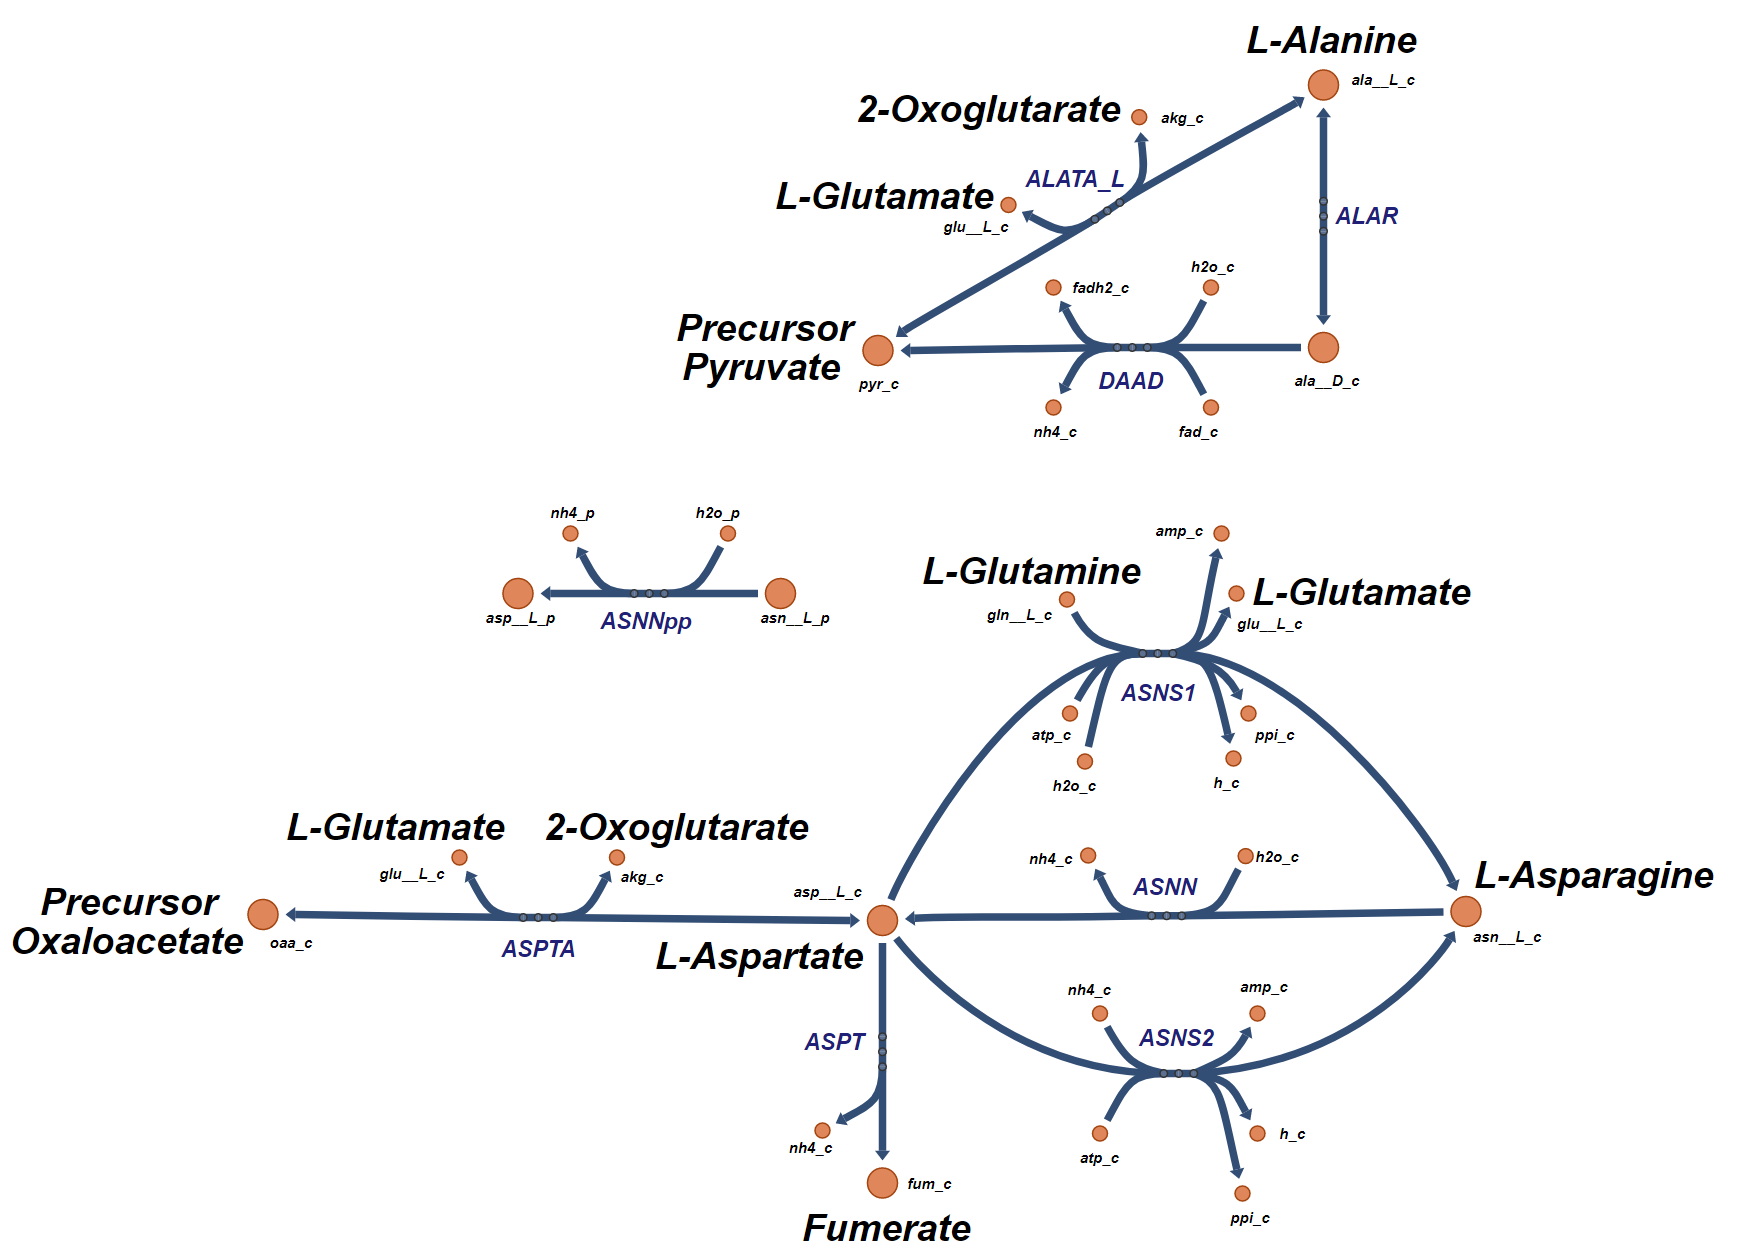

**Figure 1.** The reactions and pathways associated with the "Alanine and Aspartate Metabolism" subsystem.

The  "Alanine and Aspartate Metabolism" subsystem includes the reaction ('ASPTA') which converts the precursor oxalacetate ('oaa_c') to L-aspartate ('asp__L_c'), reactions ('ASNN', 'ASNS1', and 'ASNS2') that convert L-aspartate to L-asparagine ('asn__L_c'), a reaction ('ASPT') that converts L-aspartate to fumerate ('fum_c'), three reactions ('ALATA_L', 'DAAD', and 'ALAR') that conver the precursor pyruvate ('pyr_c') to L-alanine, and finally a reaction ('ASNNpp") that converts periplasmic L-aspartate to periplamic L-asparagine.

Let's look at the active reactions in the "Alanine and Aspartate Metabolism" subsystem under aerobic conditions. 

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(alanineAspartateReactions, round(FBAsolution.x(alanineAspartate_rxnID),3))

ALAR	0.041	
ALATA_L	-0.571	
ASNN	0	
ASNNpp	0	
ASNS1	0	
ASNS2	0.237	
ASPT	0	
ASPTA	-2.876	
DAAD	0	


From this it can be seen that the primary L-aspartate pathway includes one reaction 'ASPTA'  This pathway begins with oxaloacetate and ends with L-aspartate and supports a flux rate of -2.876 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ (the negative value is the result of the bidirectionality of the reaction). To support the biosynthesis of L-alanine from the precursor pyruvate requires the reaction 'ALATA_L' with a flux rate of -.571 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$. Note that a small amount of the L-alanine flux (0.041 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$) is converted to D-alanine through the reaction 'ALAR'.

Below is an Escher [3] figure of the  "Alanine and Aspartate Metabolism" subsystem in an aerobic condition using "Aerobic_Reaction_Flux.csv" as the data file.

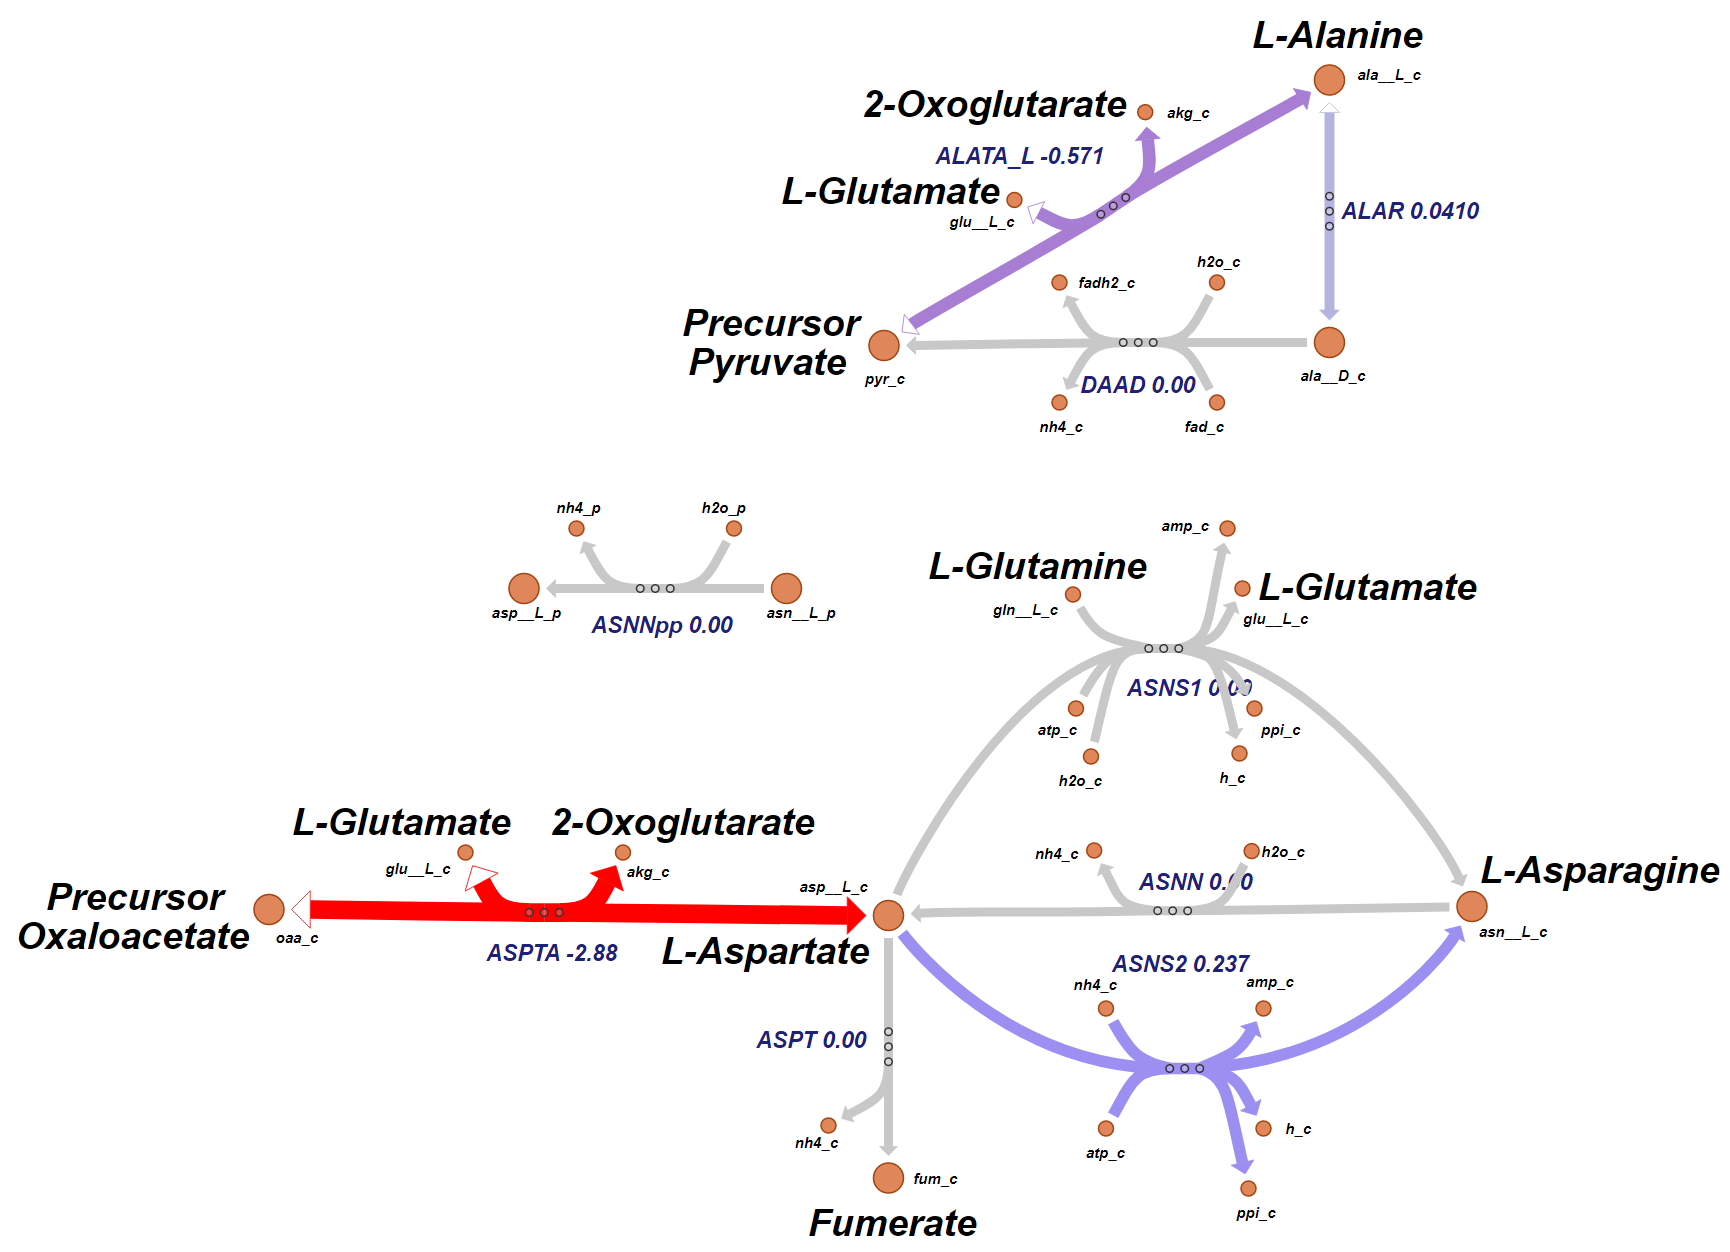

**Figure 2.** Flux through the "Alanine and Aspartate Metabolism" subsystem under aerobic conditions.

Now let's begin exploring the biosynthesis pathways for L-alanine, L-aspartate, and L-arginine.

## **3. L-Alanine Biosynthesis**

L-alanine is one of the simplest α-amino acids The α-carbon atom of alanine is bound to a methyl group (-CH3) resulting in alanine's classification as an aliphatic amino acid. The right-handed form of Alanine, D-alanine is found in bacterial cell walls and in some peptide antibiotics.

## 3.1. L-Alanine Biosynthesis Pathways

According to the "Alanine and Aspartate Metabolism" subsystem there are only three reactions that produce L-Alanine;  'ALATA_L', 'ALAR', and 'DAAD'. The first of these reactions ('ALATA_L) provides the single reaction pathway from the L-alanine precursor pyruvate. The second reaction ( 'ALAR') is a bidirectional reaction that converts D-Alanine ('ala__D_c') to L-alanine. The third of these reaction converts D-alanine to pyruvate. To explore the posssibility of other L-alanine production pathways we can use the sufNet function we can identify all the reactions that can directly produce L-alanine.

surfNet(model, 'ala__L_c')


Met #255  ala__L_c, L-Alanine, C3H7NO2
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

By looking at the bottome of this print-out we can see that there are seven reactions, when operating in the forward direction, can produce L-alanine; including 'ALAabcpp', 'ALAt2pp_copy1', 'ALAt2pp_copy2', 'ALAt4pp', 'CYSSADS', 'ICYSDS', 'LALGP', 'SCYSDS'. Notice that all these reactions, except 'ALAt2pp_copy2', are irreversible which implies that flux can only flow in the forward direction. By looking at the "Consuming reactions" listed about the "Producing reactions" you will notice that there are three reversible reactions that include 'ALAR', 'ALATA_L', and 'VPAMTr'. When these reactions are operating in the reverse direcdtion they will also be L-alanine producers.

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-alanine.

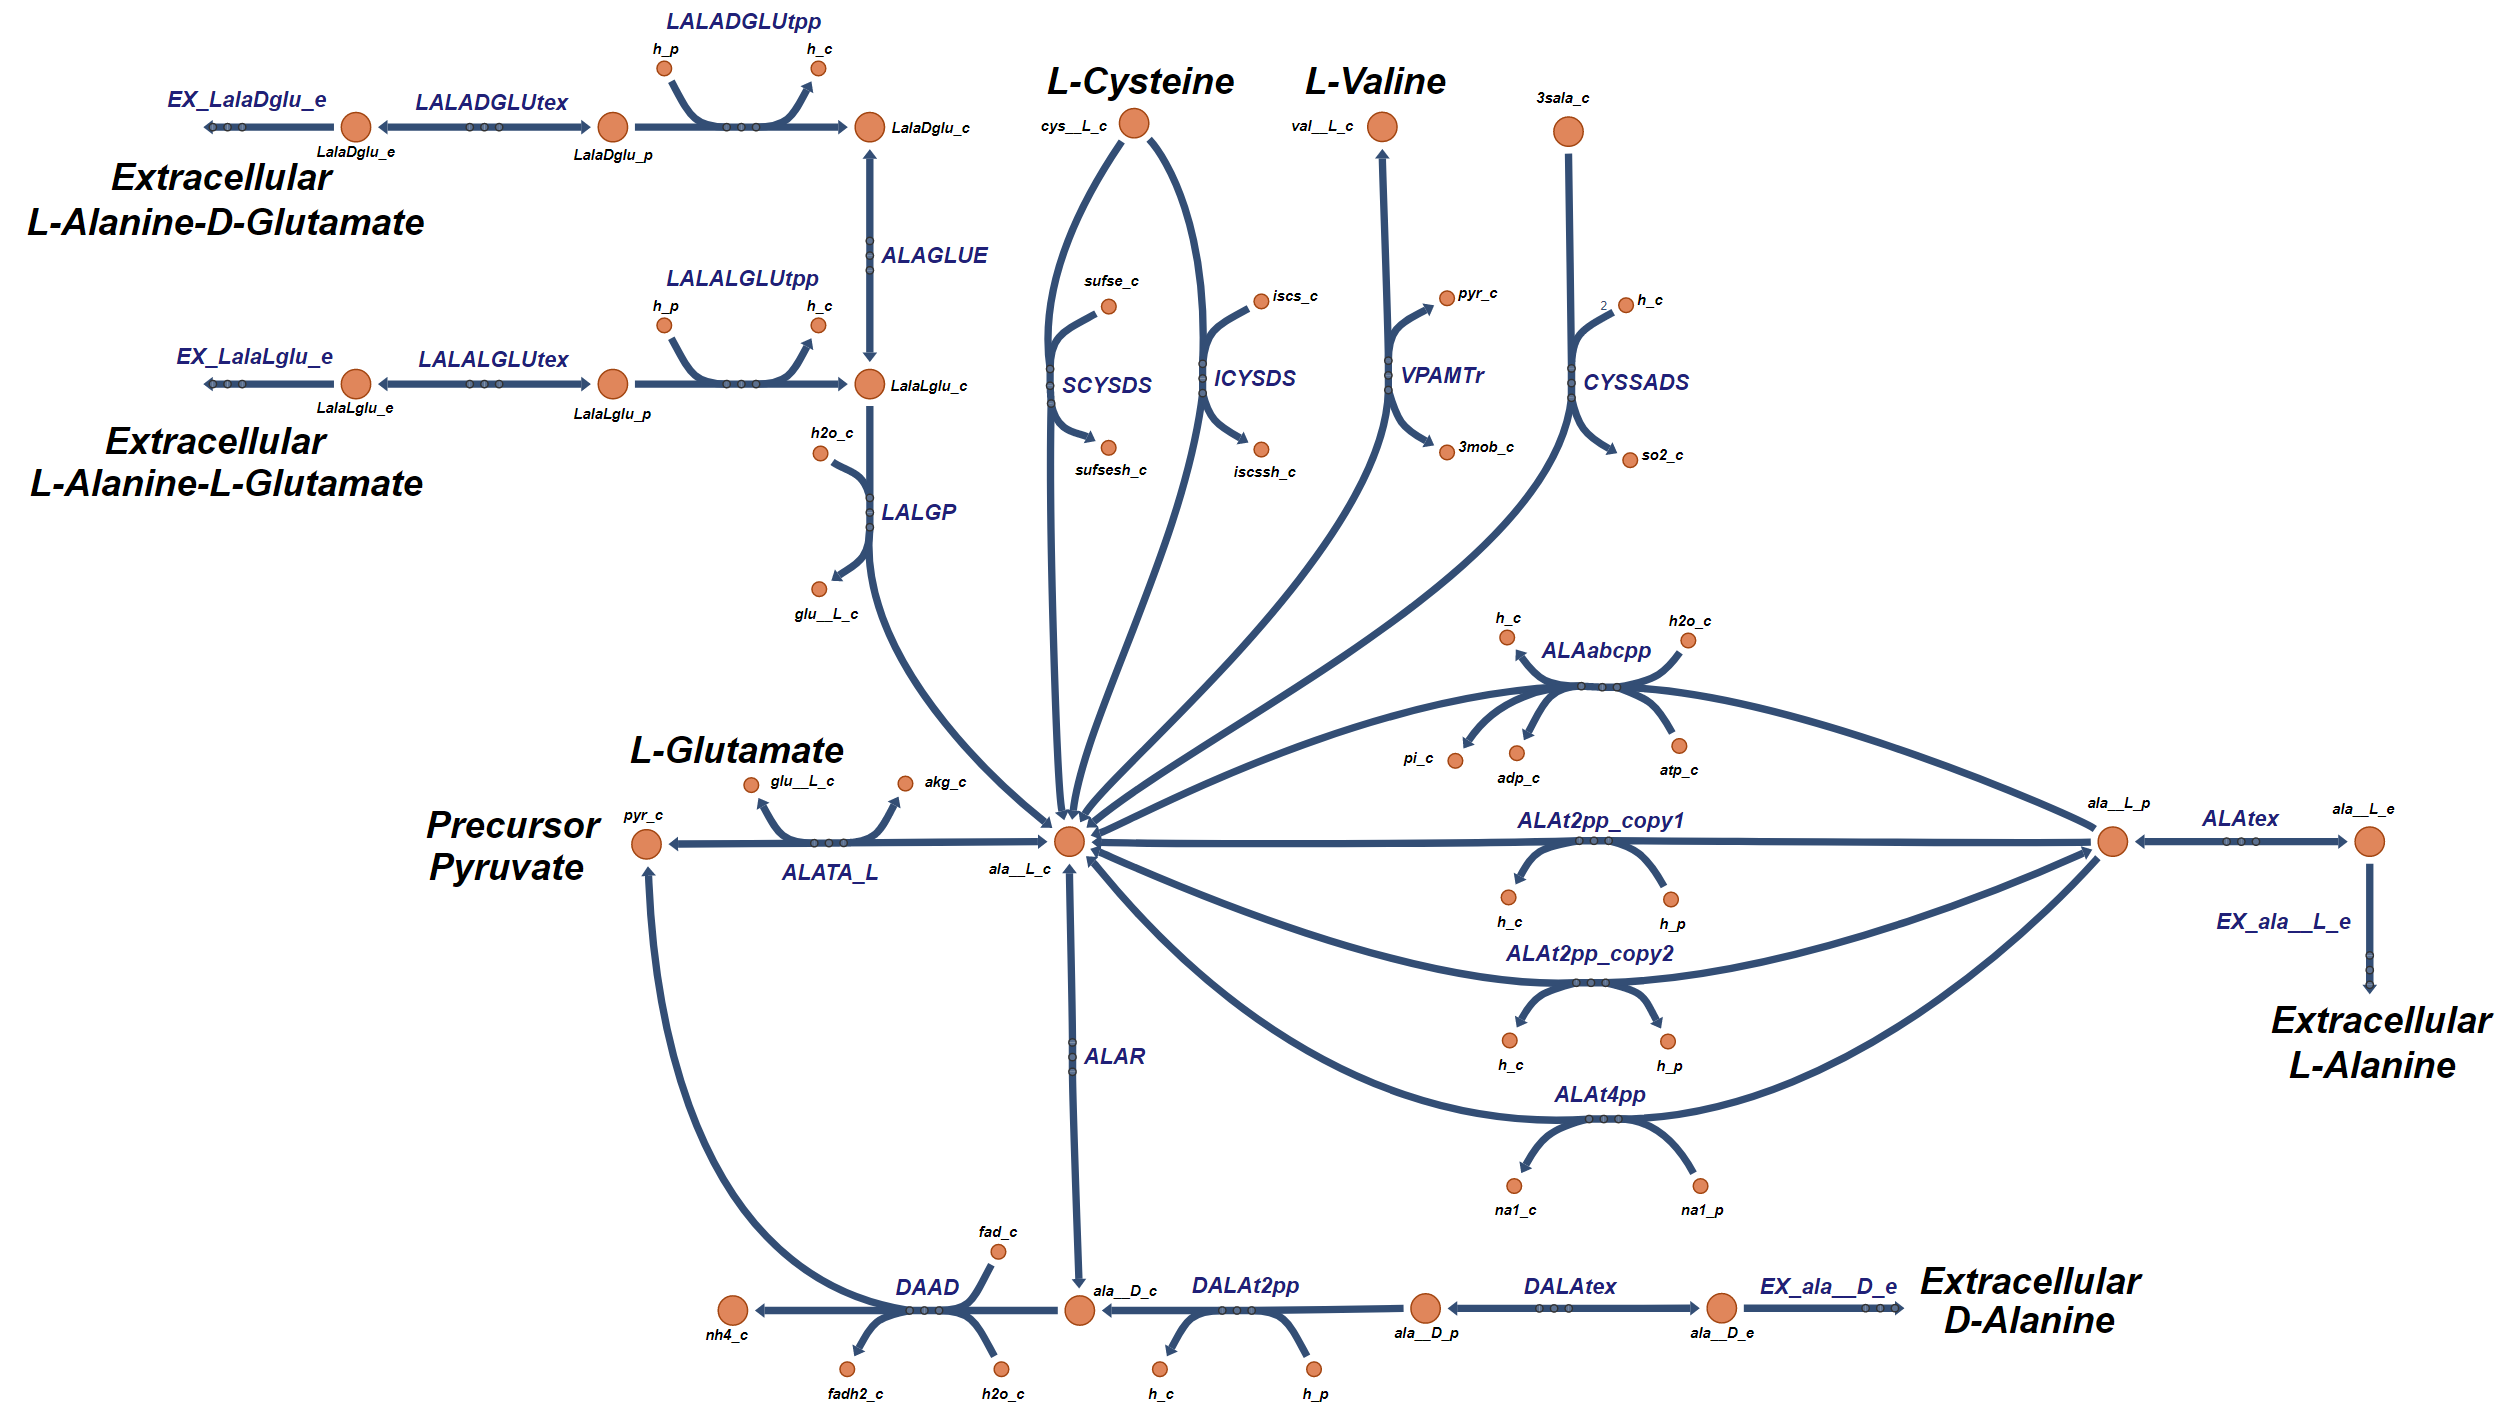

**Figure 3.** Biosynthesis pathways for the production of L-alanine.

The Escher tool allows easy access to the reactions that precede these final L-alanine producing reactions. Using this tool we can notice several different paths that can lead to L-alanine production. Let's start by looking at the pathway on the upper left of this figure. This pathway provides the conversion from extracellular L-Alanine-D-Glutamate ('LalaDglu_e') to L-alanine through 5 reactions ('EX_LalaDglu_e', 'LALADGLUtex', 'LALADGLUtpp', 'ALAGLUE', and 'LALGP'). A simlar pathway, located below it, provides the conversion from extracellular L-Alanine-L-Glutamate ('LalaLglu_e') to L-alanine through 4 reactions ('EX_LalaLglu_e', 'LALALGLUtex', 'LALALGLUtpp', and 'LALGP'). On the top of this figure there are 4 other pathways the can lead to the production of L-alanine. The first two begine with L-cysteine ('cys__L_c') as the initial substrate and use either 'SCYSDS or ICYSDS' to create the L-alanine product.There is another pathways that begins with L-valine ('val__L_c') and uses VPAMTr to create the L-alanine. In the model, there is another pathway that uses the reaction 'CYSSADS', unfortunately this is a dead-end reaction since there is no way for the intiial substrate 3-Sulfino-L-Alanine ('3sala_c') to be created within the model. To the left of the figure is the primary pathway that starts with the precursor pyrvate ('pyr_c') and uses the reaction 'ALATA_L'. Another path that can begin with pyruvate includes 'DAAD' and 'ALAR'. On the right bottom is a pathway that begins with extracellular D-alanine ('ala__D_e') and passes through four reactions ('EX_ala__D_e',  'DALAtex', 'DALAt2pp', and 'ALAR') in the process of conversion to L_alanine. Finally, there are four transporters ('ALAabcpp', 'ALAt2pp_copy1', 'ALAt2pp_copy2', and 'ALAt4pp') that can transport diffused extracellular L-alanine ('ala__L_e') into the cytoplasm.

## 3.2 L-Alanine Aerobic Operation

The fluxes for these L-Alanine producing reactions can be extracted from the iJO1366 model as follows.

alanineReactions = transpose({'ALATA_L','DAAD','ALAR','ALAabcpp','ALAt2pp_copy1','ALAt2pp_copy2','ALAt4pp',...
    'EX_ala__D_e','DALAtex','DALAt2pp','EX_LalaDglu_e','LALADGLUtex','LALADGLUtpp','ALAGLUE',...
    'EX_LalaLglu_e','LALALGLUtex','LALALGLUtpp','LALGP','SCYSDS','ICYSDS','VPAMTr','CYSSADS'});
[tmp,alanine_rxnID] = ismember(alanineReactions,model.rxns);
reactionNames = model.rxnNames(alanine_rxnID);
reactionSubsystem = model.subSystems(alanine_rxnID);
T = table(reactionNames,reactionSubsystem,'RowNames',alanineReactions)

T = 22×2 table
                                                    reactionNames                                                reactionSubsystem              
                     ___________________________________________________________________________    ____________________________________________

    ALATA_L          'L-alanine transaminase'                                                       'Alanine and Aspartate Metabolism'          
    DAAD             'D-Amino acid dehydrogenase'                                                   'Alanine and Aspartate Metabolism'          
    ALAR             'Alanine racemase'                                                             'Alanine and Aspartate Metabolism'          
    ALAabcpp         'L-alanine transport via ABC system (periplasm)'                               'Transport, Inner Membr

Now let's explore the flux through these L-Alanine pathways under normal aerobic conditions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(alanineReactions, round(FBAsolution.x(alanine_rxnID),3))

ALATA_L	-0.571	
DAAD	0	
ALAR	0.041	
ALAabcpp	0	
ALAt2pp_copy1	0	
ALAt2pp_copy2	0	
ALAt4pp	0	
EX_ala__D_e	0	
DALAtex	0	
DALAt2pp	0.014	
EX_LalaDglu_e	0	
LALADGLUtex	0	
LALADGLUtpp	0	
ALAGLUE	0	
EX_LalaLglu_e	0	
LALALGLUtex	0	
LALALGLUtpp	0	
LALGP	0	
SCYSDS	0	
ICYSDS	0.002	
VPAMTr	0	
CYSSADS	-0	


This can be seen using an Escher [3] plot with the "Aerobic_Reaction_Flux.csv" data.

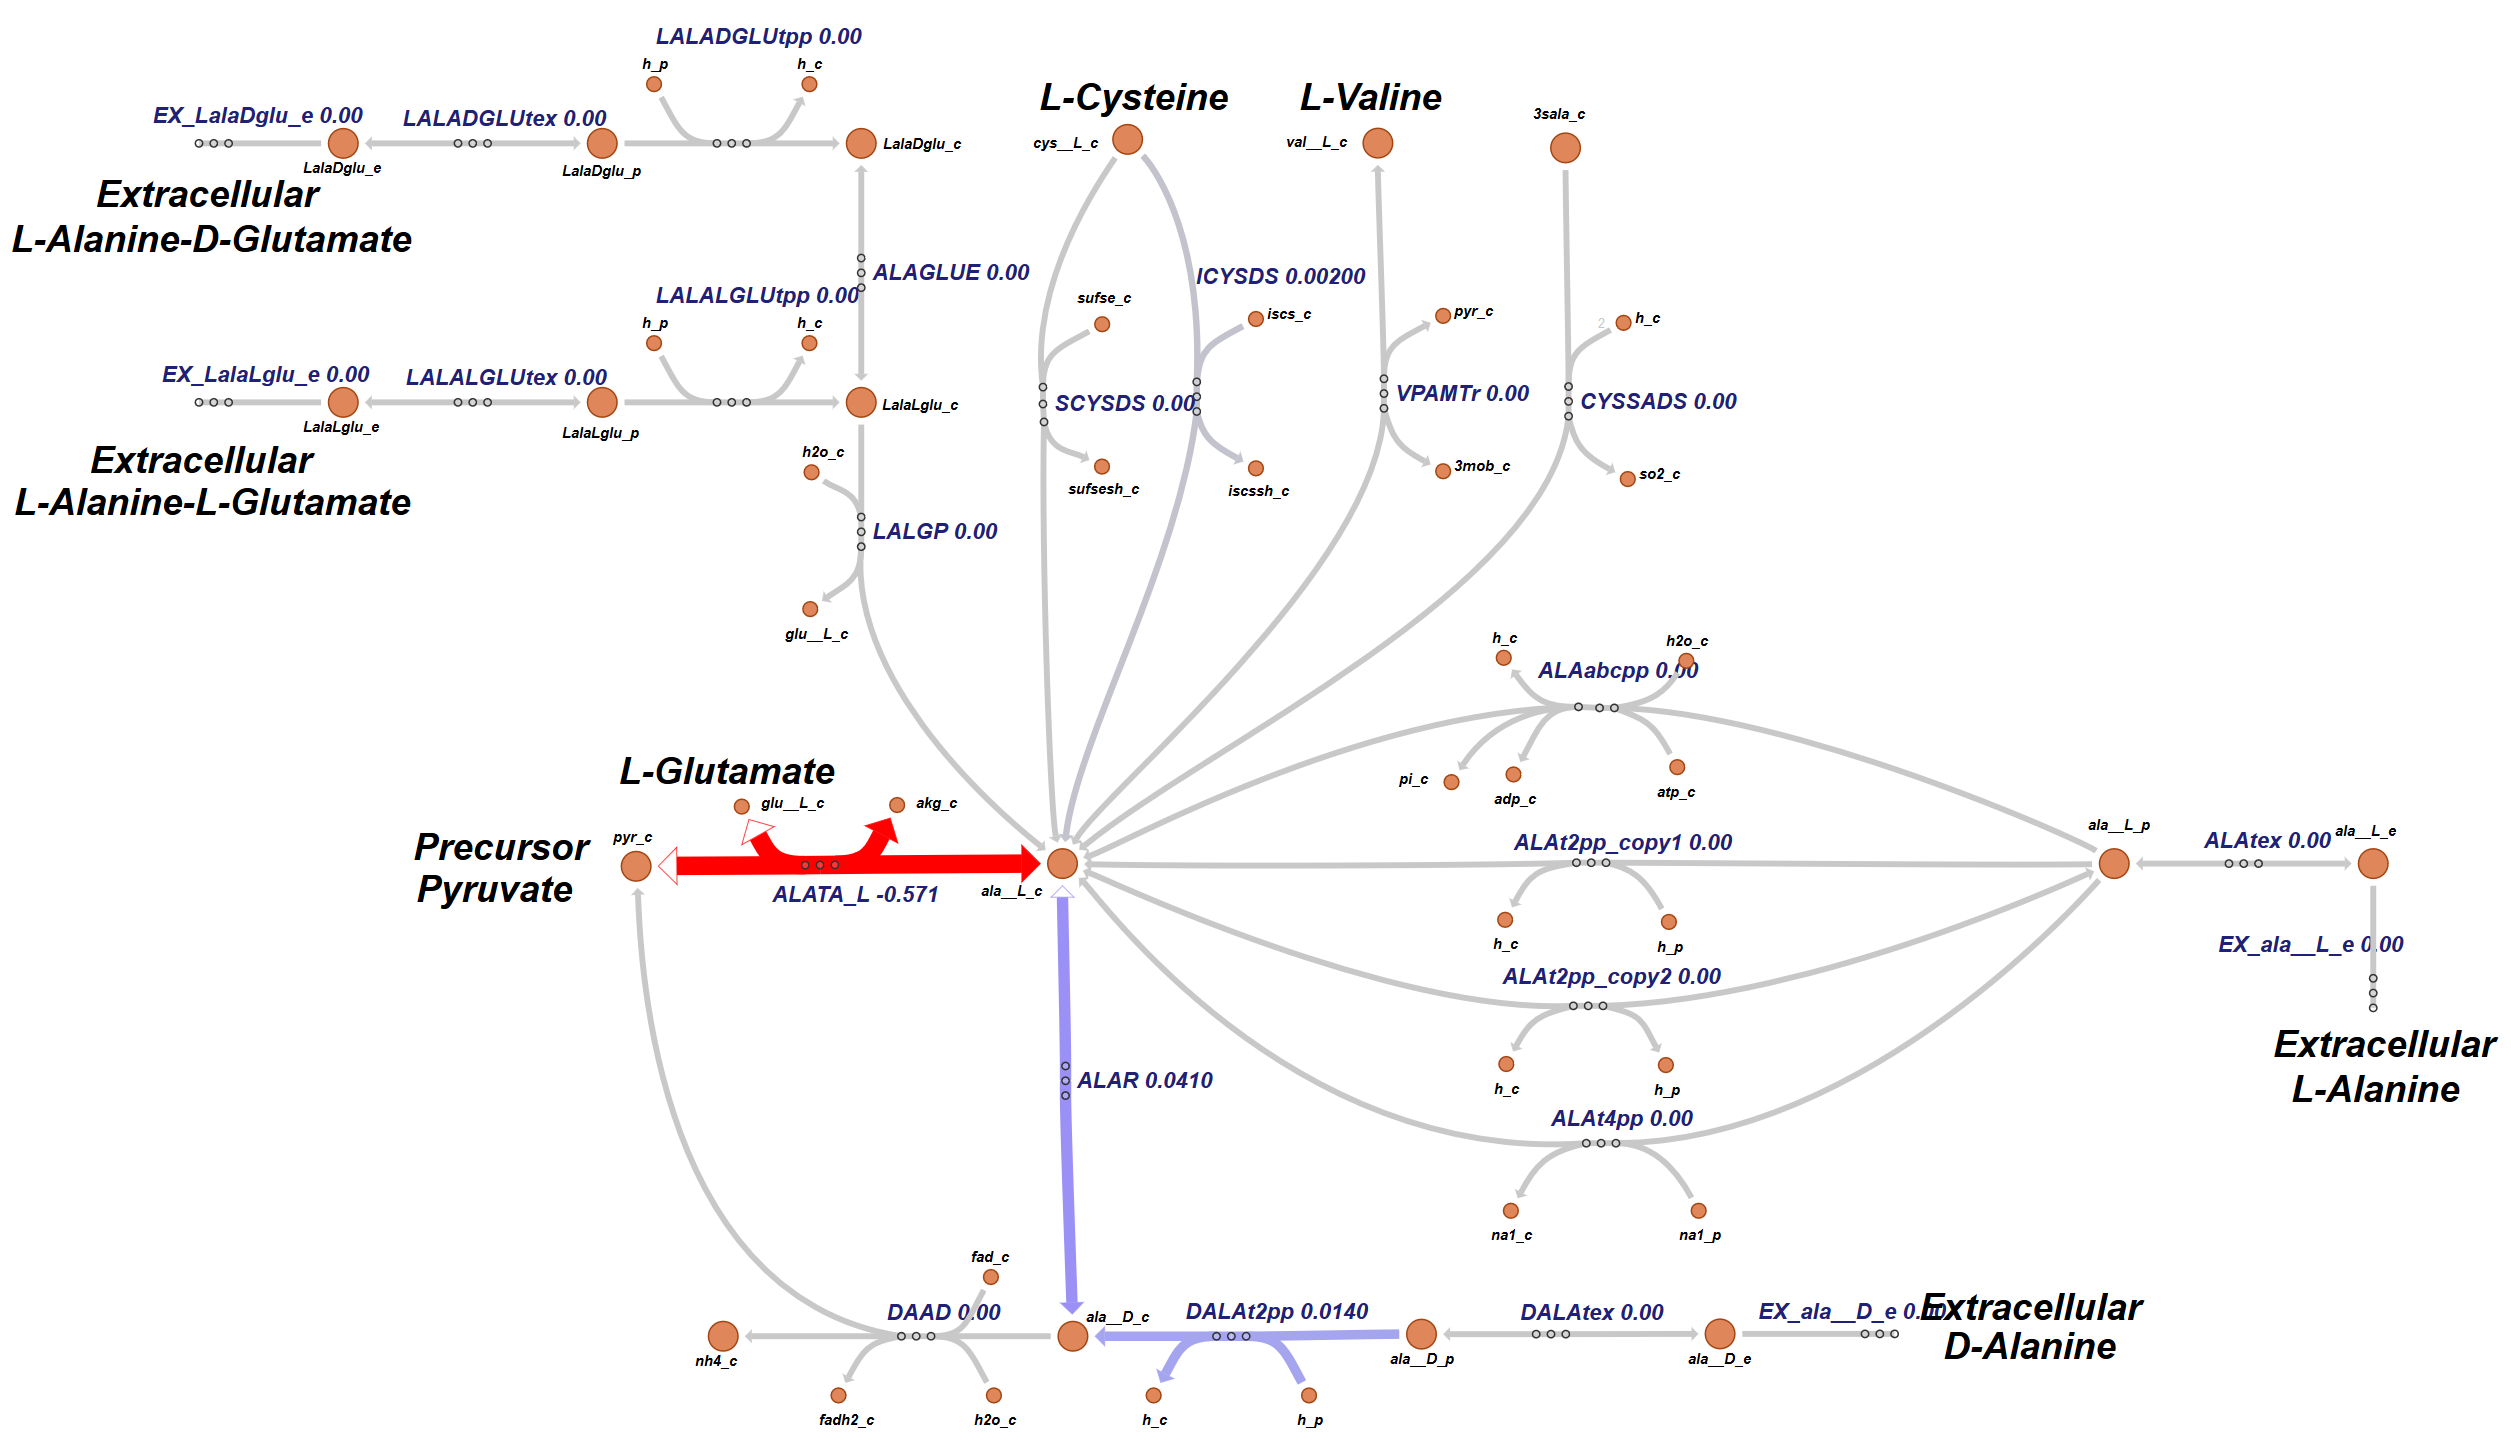

**Figure 4.** L-alanine production under aerobic conditions.

It can be seen that the majority of the L-alanine flux is produced through the primary pathway ('ALATA_L') with a small amount being contributed from the D-alanine pool ('DALAt2rpp' and 'ALAR'), and an even smaller amount from the L-cysteine pool ('ICYSDS'). 

## 3.3 Excess L-Alanine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-alanine for the desired bioproduct.  What is the maximum amount of excess L-alanine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'ala__L_c');

DM_ala__L_c	ala__L_c 	->	


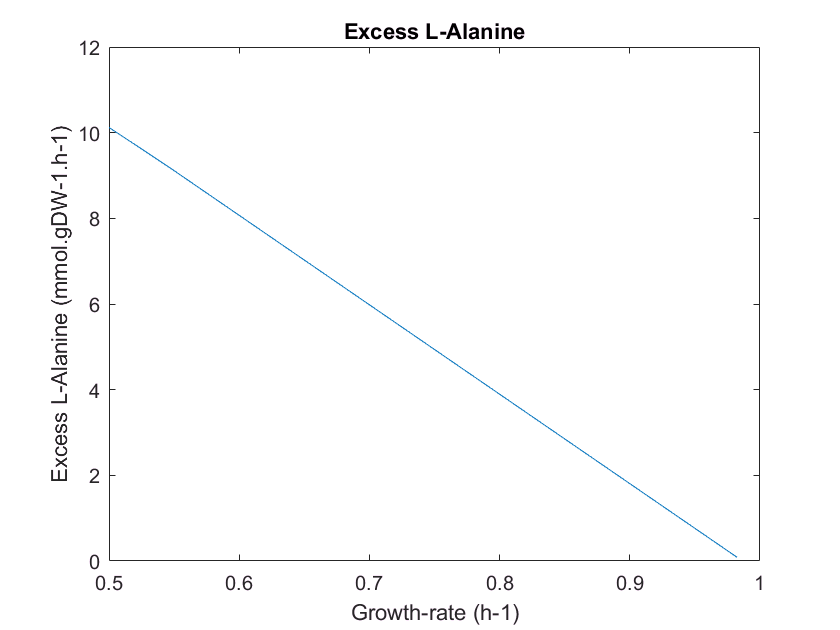

[tmp,alanine_MAX_rxnID] = ismember({'DM_ala__L_c'},model.rxns);
model = changeObjective(model,'DM_ala__L_c'); % Set the objective function
FBAsolution_Alanine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessAlanine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Alanine = optimizeCbModel(model,'max'); % Perform FBA
    excessAlanine(i) = FBAsolution_Alanine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessAlanine)
title('Excess L-Alanine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Alanine (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of L-alanine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-alanine increases the growth-rate will need to decrease. In this figure we can see that the excess L-alanine flux can increase from 0.08649 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 10.12 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-alanine flux beyond these levels will require using the pathways that allow for the transport of L-alanine from the extracellular media. 

## **4. L-Aspartate Biosynthesis**

L-aspartate is xxx

## 4.1.  **L-Aspartate** Biosynthesis Pathways

According to the "Alanine and Aspartate Metabolism" subsytem in Figure 1 there are only two reactions that can produce cytoplasmic L-aspartate,  'ASNN' and 'ASPTA'. The first reaction is used to convert L-arginine ('asn__L_c' ) to L-aspartate ('asp__L_c'). The second reaction ('ASPTA' ) is a reversible reaction that serves as the primary pathway for the L-asparate precursor oxaloacetate ('oaa_c'). 

To explore the posssibility of other L-aspartate production pathways, we can use the "surfNet" COBRA toolbox function to identify all the reactions that can produce L-aspartate.

surfNet(model, 'asp__L_c')


Met #302  asp__L_c, L-Aspartate, C4H6NO4
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

From these results we can see that there are seven reactions that produce cytoplasmic L-aspartate in the forward direction, they include  'ASNN', 'ASPabcpp', 'ASPt2_2pp', 'ASPt2_3pp', 'ASPt2pp_copy1', 'ASPt2pp_copy2', and 'SUCASPtpp'. The rest of the reactions are transporters that can be used to uptake L-aspartate ('asp__L_p')  from the periplasm to the cytoplasmic space ('asp__L_c').  The first of these transporters is an ABC transporter ( 'ASPabcpp') that requires ATP to move to traposport the L-aspartate. The next four reactions ( 'ASPt2_2pp', 'ASPt2_3pp', 'ASPt2pp_copy1', 'ASPt2pp_copy2') require energy from the proton-motive force to transport L-aspartate. The final reaction is an antiporter that moves succinate from the cytoplasm ('succ_c' ) to the periplasm ('succ_p' ) while also move L-aspartate from the periplasm ('asp__L_p') to the cytoplasm ('asp__L_c'). 

Other reactions that could act to produce L-aspartate are the reversible reactions listed under the "Consuming reactions" produced above by surfNet. These reversible reactions include 'ASPK' and 'ASPTA'. The first of these reaction ('ASPK') provides connectivity between the L-aspartate and the L-lysine & L-threonine metabolism. While the second reaction ('ASPTA') serves as the primary pathway for the L-asparate precursor oxaloacetate ('oaa_c').

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-aspartate.

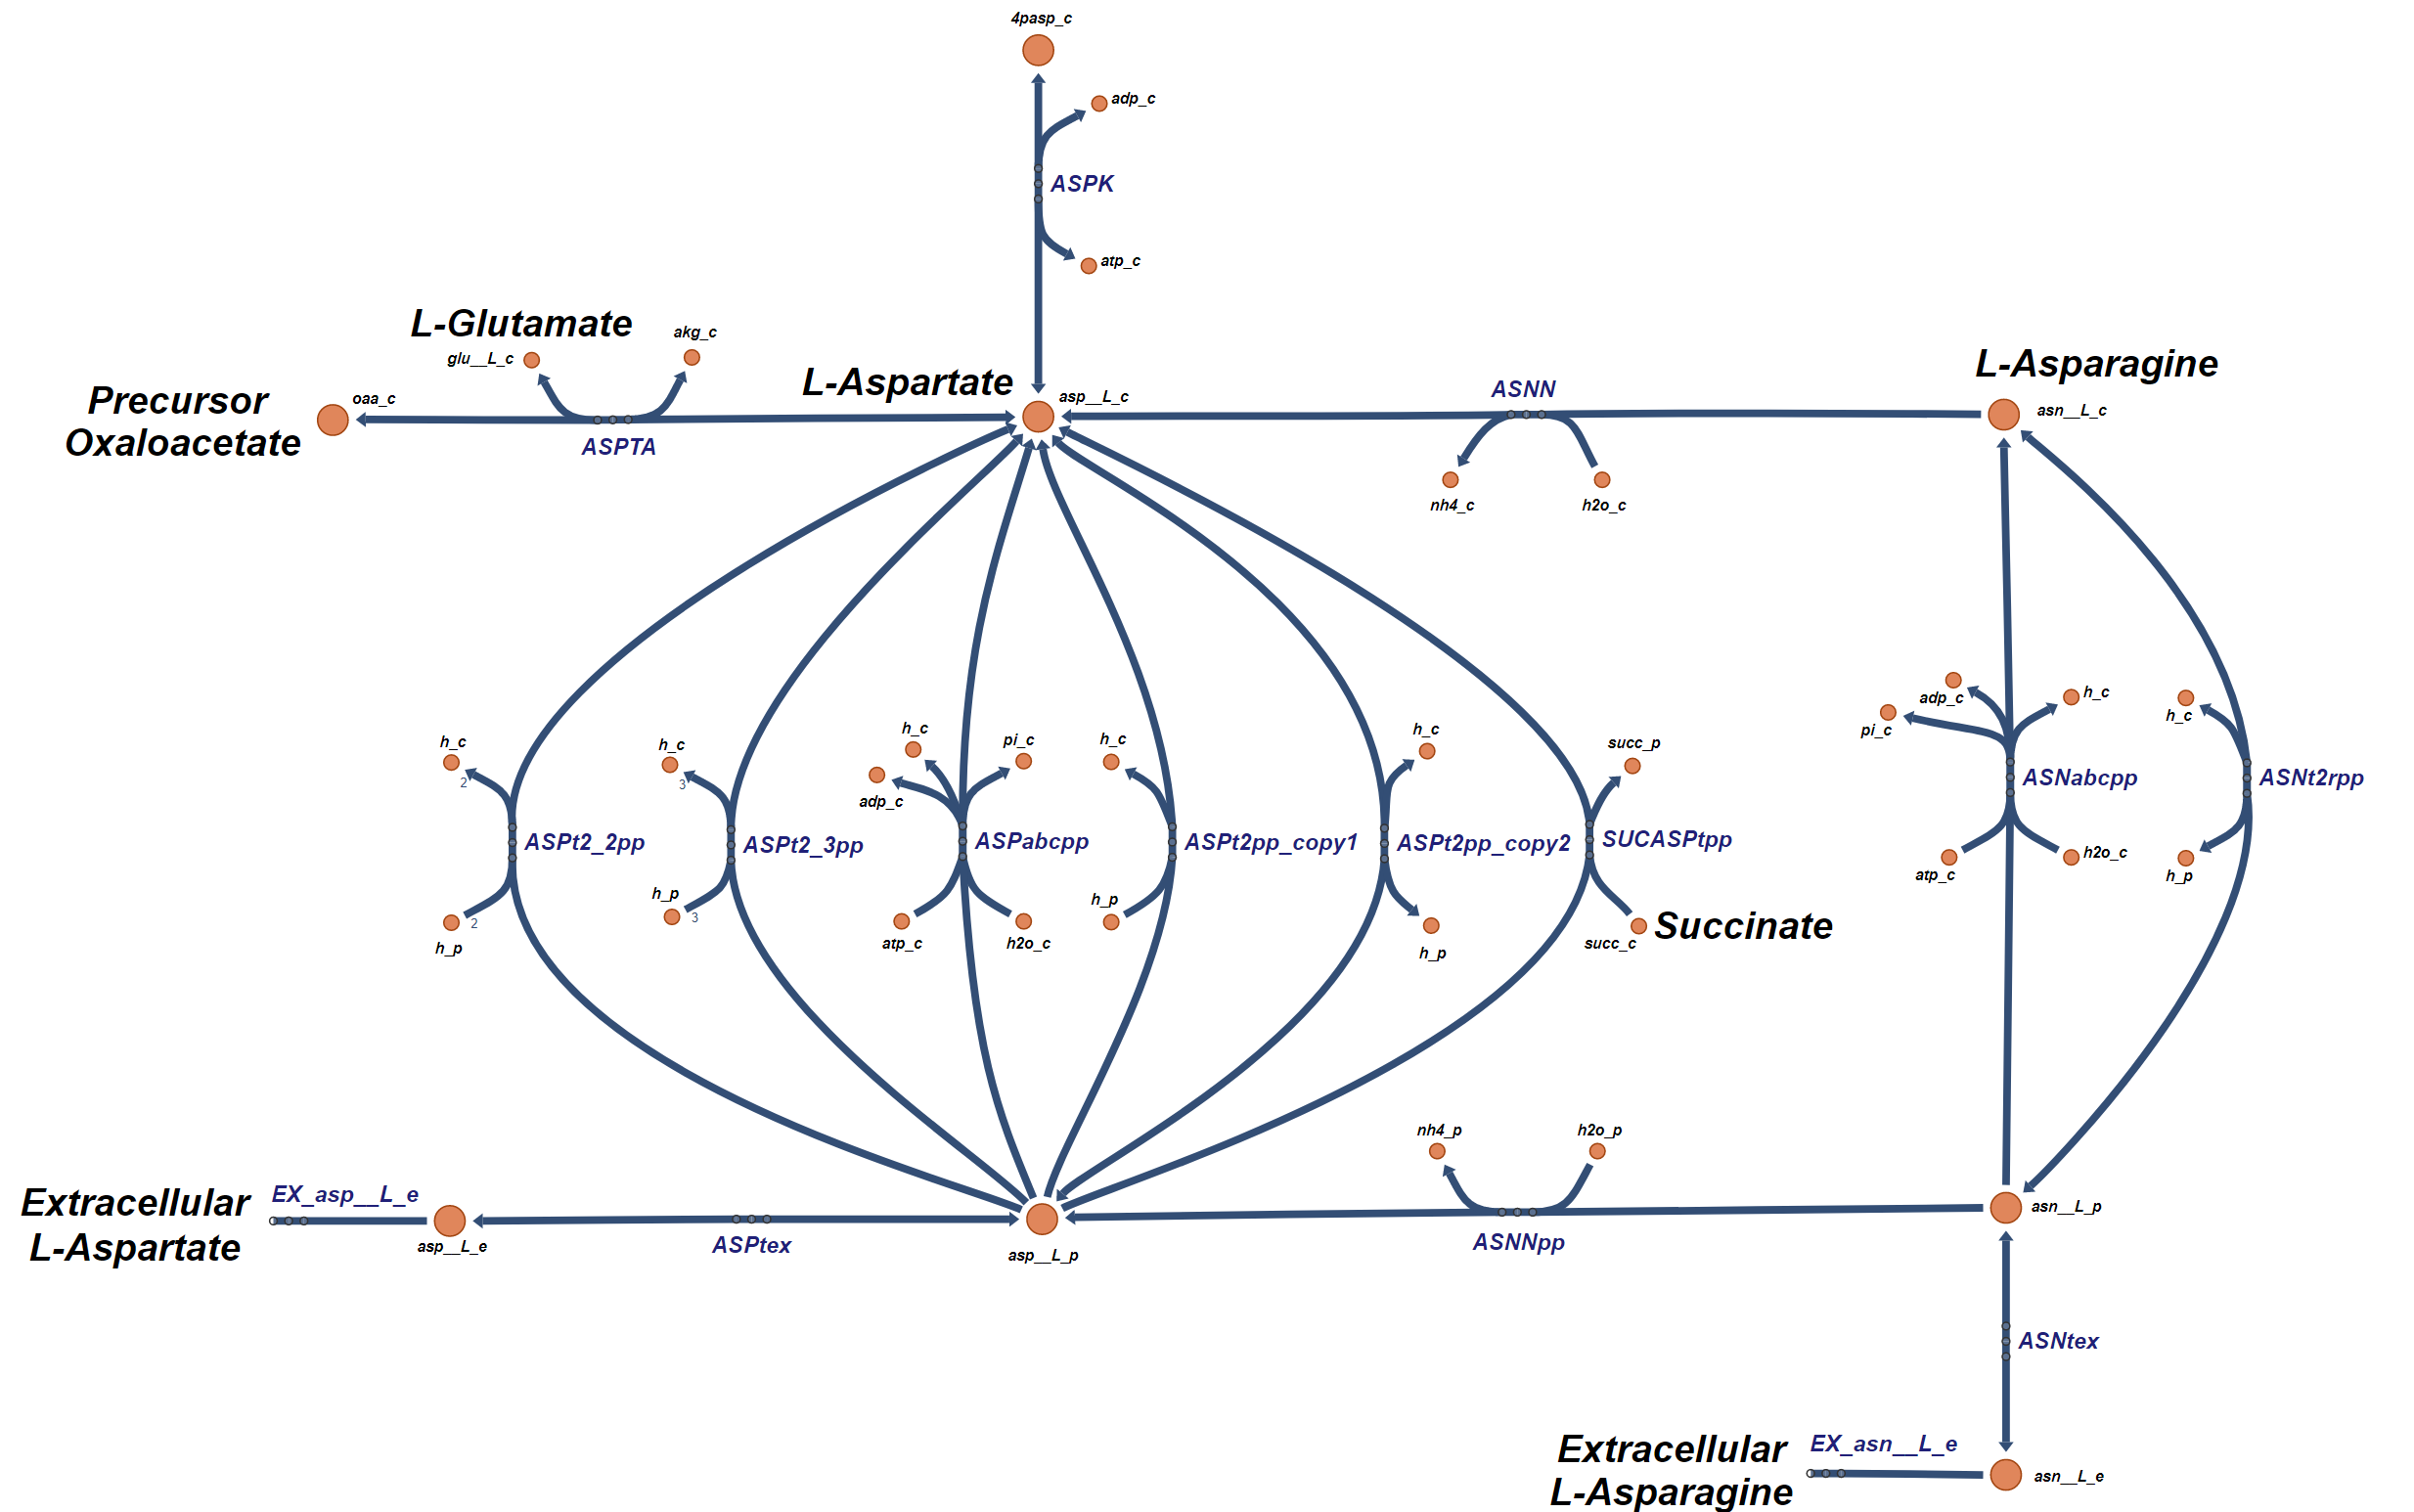

**Figure 6. **Biosynthesis pathways for the production of L-aspartate.

Now with this information we can define the reactions that create the pathways for the production of intercellular L-Aspartate, they include 'ASPTA', 'ASNN', 'ASPabcpp', 'ASPt2_2pp', 'ASPt2_3pp', 'ASPt2pp_copy1', 'ASPt2pp_copy2', and 'SUCASPtpp'. Now let's explore the potential pathways that lead to the production of L-aspartate. The primary pathway begins with the precursor oxaloacetate and passes through the 'ASPTA' reaction. A second collection of pathways begins with extracellular L-aspartate that diffuses into the periplasm ('EX_asp__L_e' and 'ASPtex') where it can be transported to the cytoplasm by one or more of the six available transporters ('ASPt2_2pp', 'ASPt2_3pp', 'ASPabcpp', 'ASPt2pp_copy1', 'ASPt2pp_copy2', and/or 'SUCASPtpp'). Another set of pathways that can produce L-asparate begins with extracellular L-asparagine where it can diffuse ('EX_asn__L_e' and 'ASNtex') into the cell's periplasm. At this point, the periplasmic L-asparagine can be converted into periplasmic L-aspartate through the reaction 'ASNNpp' where it can follow the previosuly described pathay to L-aspartate or it can be transported into the cytoplasm ('ASNabcpp' and/or 'ASNt2rpp') where it can be converted into L-aspartate through 'ASNN'. Finally, there is the reaction ('ASPK') which provides connectivity between the L-aspartate and the L-lysine & L-threonine metabolism.

aspartateReactions = transpose({'ASPTA','EX_asp__L_e','ASPtex','ASPabcpp','ASPt2_2pp','ASPt2_3pp','ASPt2pp_copy1','ASPt2pp_copy2','SUCASPtpp',...
    'EX_asn__L_e','ASNtex', 'ASNNpp','ASNabcpp','ASNt2rpp','ASNN','ASPK'});
[tmp,aspartate_rxnID] = ismember(aspartateReactions,model.rxns);
reactionNames = model.rxnNames(aspartate_rxnID);
reactionSubsystem = model.subSystems(aspartate_rxnID);
T = table(reactionNames,reactionSubsystem,'RowNames',aspartateReactions)

T = 16×2 table
                                                reactionNames                                       reactionSubsystem         
                     ___________________________________________________________________    __________________________________

    ASPTA            'Aspartate transaminase'                                               'Alanine and Aspartate Metabolism'
    EX_asp__L_e      'L-Aspartate exchange'                                                 ''                                
    ASPtex           'L-aspartate transport via diffusion (extracellular to periplasm)'     'Transport, Outer Membrane Porin' 
    ASPabcpp         'L-aspartate transport via ABC system (periplasm)'                     'Transport, Inner Membrane'       
    ASPt2_2pp        'Aspartate transport via proton symport (2 H) (p

A table showing these reactions, the reaction name and the reaction formula is given below.

reactionFormulas = printRxnFormula(model,aspartateReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',aspartateReactions)

T = 16×2 table
                                                reactionNames                                                     reactionFormulas                       
                     ___________________________________________________________________    _____________________________________________________________

    ASPTA            'Aspartate transaminase'                                               'akg_c + asp__L_c  <=> glu__L_c + oaa_c '                    
    EX_asp__L_e      'L-Aspartate exchange'                                                 'asp__L_e  -> '                                              
    ASPtex           'L-aspartate transport via diffusion (extracellular to periplasm)'     'asp__L_e  <=> asp__L_p '                                    
    ASPabcpp         'L-aspartate transport via ABC system (periplasm)'       

## 4.2. L-Aspartate Aerobic Operation

Now let's explore the flux through these L-aspartate pathways under normal aerobic conditions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(aspartateReactions, round(FBAsolution.x(aspartate_rxnID),3))

ASPTA	-2.876	
EX_asp__L_e	0	
ASPtex	0	
ASPabcpp	0	
ASPt2_2pp	0	
ASPt2_3pp	0	
ASPt2pp_copy1	0	
ASPt2pp_copy2	0	
SUCASPtpp	0	
EX_asn__L_e	0	
ASNtex	0	
ASNNpp	0	
ASNabcpp	0	
ASNt2rpp	0	
ASNN	0	
ASPK	1.05	


In this condition we can see that the only pathway for L-aspartate production is from the precursor 'oaa_c' using the 'ASPTA' reaction. There is a small amount of L-aspartate flux that is leaving the pool through 'ASPK'.

## 4.3 Excess L-Aspartate Production

When a cell is producing a recombinant protein, it might be required to produce additional L-aspartate for the desired bioproduct.  What is the maximum amount of excess L-aspartate, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'asp__L_c');

DM_asp__L_c	asp__L_c 	->	


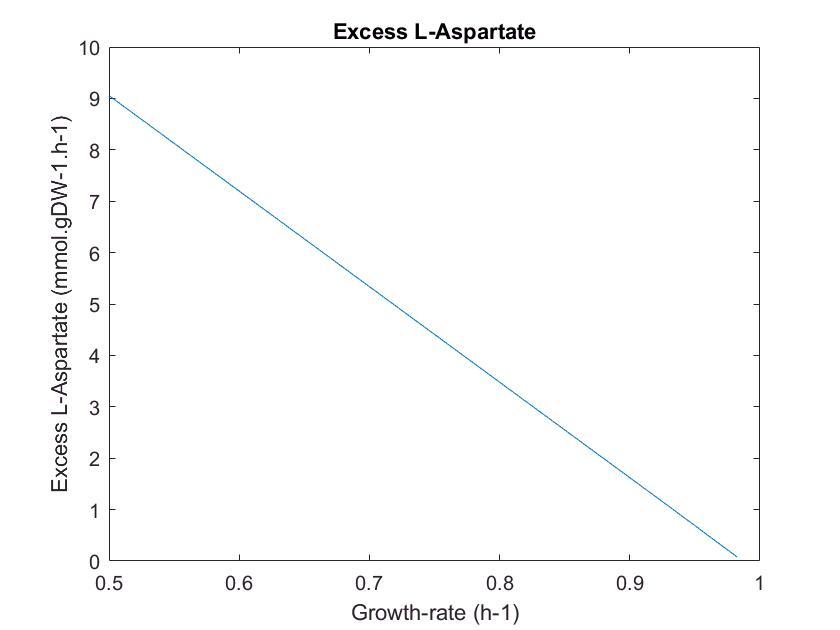

[tmp,alanine_MAX_rxnID] = ismember({'DM_asp__L_c'},model.rxns);
model = changeObjective(model,'DM_asp__L_c'); % Set the objective function
FBAsolution_Aspartate = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessAspartate = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Aspartate = optimizeCbModel(model,'max'); % Perform FBA
    excessAspartate(i) = FBAsolution_Aspartate.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessAspartate)
title('Excess L-Aspartate'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Aspartate (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of L-alanine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-alanine increases the growth-rate will need to decrease. In this figure we can see that the excess L-alanine flux can increase from 0.07801 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 9.055 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-alanine flux beyond these levels will require using the pathways that allow for the transport of L-alanine from the extracellular media. 

## **4. L-Asparagine Biosynthesis**

L-Asparagine is xxx

## 4.1.  **L-Asparagine** Biosynthesis Pathways

According to the "Alanine and Aspartate Metabolism" subsystem (see Figure 1), which includes L_asparagine,  there is only two reactions that can produce cytoplasmic L-asparagine,  'ASNS1', 'ASNS2''. Both of these reaction convert  L-arpartate ('asp__L_c' ) to L-asparagine ('asn__L_c'). It is also important to note that both of these paths also require ATP. The pathway from the precursor oxaloacetate ('oaa_c') goes through the L-Aparartate pathway first.

To explore the posssibility of other L-Alanine production pathways we can use the "sufNet" function to identify all the reactions that can produce L-asparagine.

surfNet(model, 'asn__L_c')


Met #298  asn__L_c, L-Asparagine, C4H8N2O3
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

From these results we can see that there are four reactions that can produce cytoplasmic L-asparagine in the forward direction, they include  'ASNS1', 'ASNS2', 'ASNabcpp', and 'ASNt2rpp'. The first two reactions were described above. The rest of the reactions are transporters that can be used to uptake L-asparagine ('asn__L_p')  from the periplasm to the cytoplasmic space ('asn__L_c').  The first of these transporters is an ABC transporter ( 'ASNabcpp') that requires ATP to move to transport the L-asparagine. The last reactions ( 'ASNt2rpp') require energy from the proton-motive force to transport L-asparagine. There are also no bidirectional "Consuming reactions' listed that can produce L-asparagine.

Now with this information we can define the reactions that create the pathways for the production of L-Aspartate, they include  'ASNS1', 'ASNS2', 'ASNabcpp', and 'ASNt2rpp'.

asparagineReactions = transpose({'ASNS1','ASNS2','ASNabcpp','ASNt2rpp'});
[tmp,asparagine_rxnID] = ismember(asparagineReactions,model.rxns);
reactionNames = model.rxnNames(asparagine_rxnID);
reactionSubsystem = model.subSystems(asparagine_rxnID);
T = table(reactionNames,reactionSubsystem,'RowNames',asparagineReactions)

T = 4×2 table
                                          reactionNames                                       reactionSubsystem         
                __________________________________________________________________    __________________________________

    ASNS1       'Asparagine synthase (glutamine-hydrolysing)'                         'Alanine and Aspartate Metabolism'
    ASNS2       'Asparagine synthetase'                                               'Alanine and Aspartate Metabolism'
    ASNabcpp    'L-asparagine transport via ABC system (periplasm)'                   'Transport, Inner Membrane'       
    ASNt2rpp    'L-asparagine reversible transport via proton symport (periplasm)'    'Transport, Inner Membrane'       


A table showing these reactions, the reaction name and the reaction formula is given below.

reactionFormulas = printRxnFormula(model,asparagineReactions,0);
T = table(reactionNames,reactionFormulas,'RowNames',asparagineReactions)

T = 4×2 table
                                          reactionNames                                                                 reactionFormulas                                  
                __________________________________________________________________    ____________________________________________________________________________________

    ASNS1       'Asparagine synthase (glutamine-hydrolysing)'                         'asp__L_c + atp_c + gln__L_c + h2o_c  -> amp_c + asn__L_c + glu__L_c + h_c + ppi_c '
    ASNS2       'Asparagine synthetase'                                               'asp__L_c + atp_c + nh4_c  -> amp_c + asn__L_c + h_c + ppi_c '                      
    ASNabcpp    'L-asparagine transport via ABC system (periplasm)'                   'atp_c + h2o_c + asn__L_p  -> adp_c + asn__L_c + h_c + pi_c '                       
    

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-asparagine.

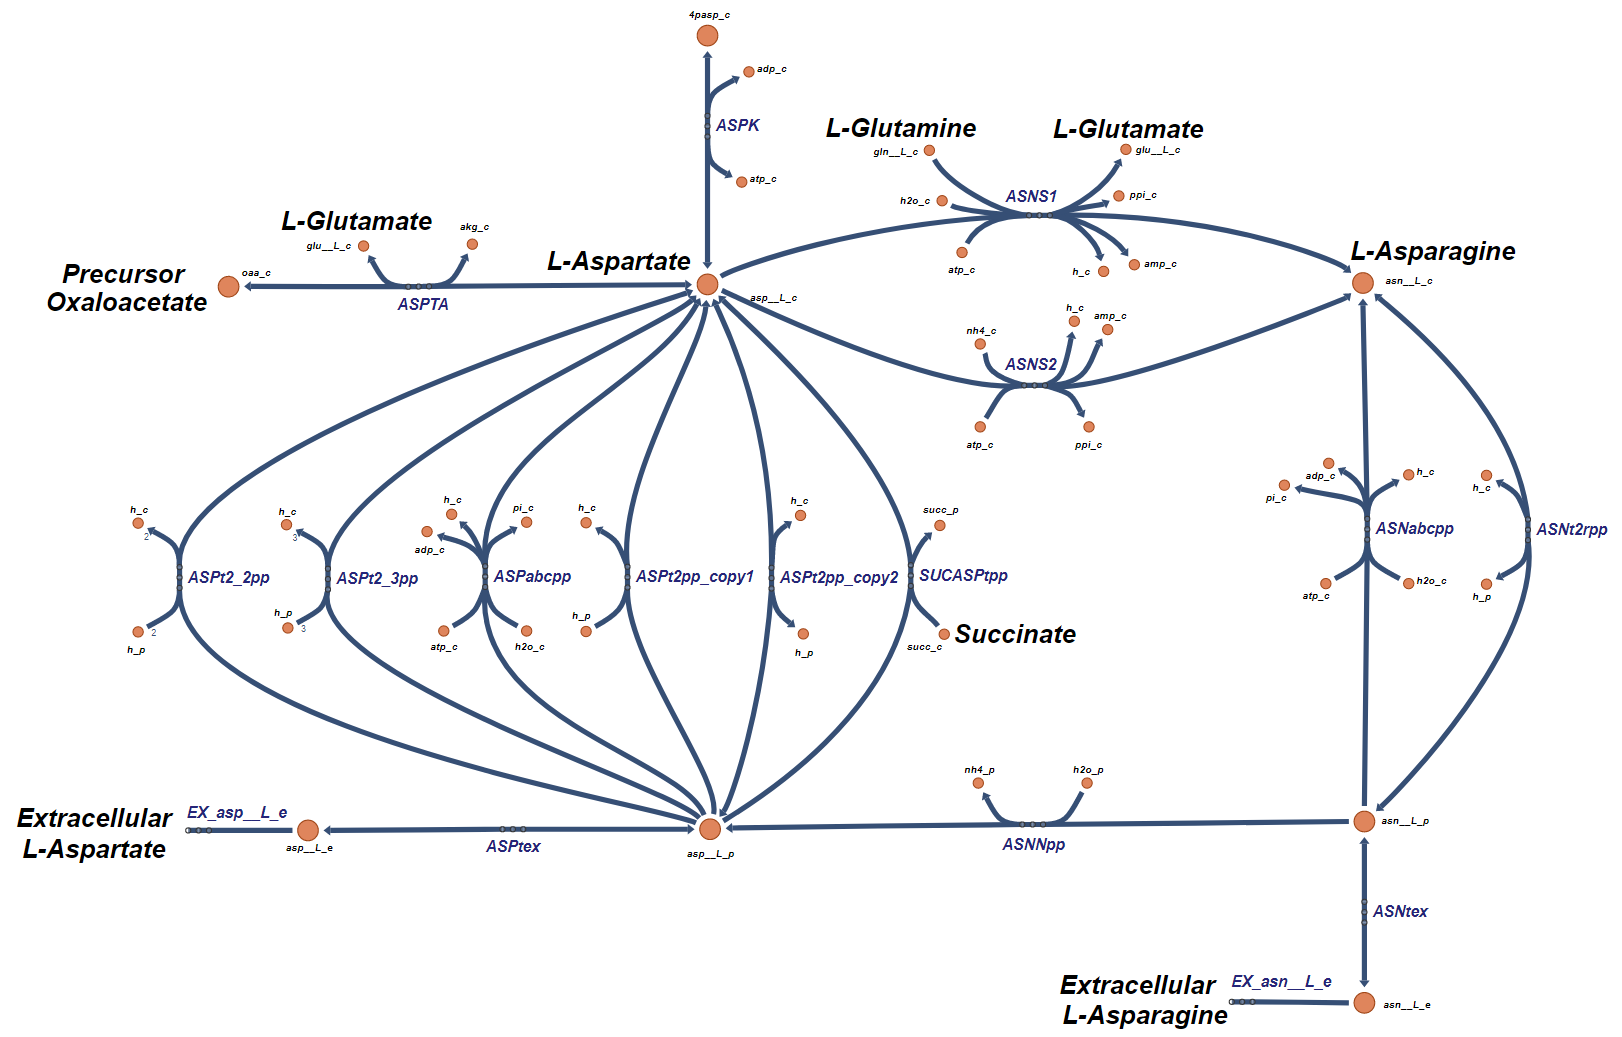

**Figure 3. **L-Asparagine production pathways.

Now let's explore the potential pathways that lead to the production of L-aspartate. The primary pathway begins with the precursor oxaloacetate ('oaa_c') and passes through the 'ASPTA', 'ASNS1' and/or 'ASNS2' reactions. A second collection of pathways begins with extracellular L-aspartate that diffuses into the periplasm ('EX_asp__L_e' and 'ASPtex') where it can be transported to the cytoplasm by one or more of the six available transporters ('ASPt2_2pp', 'ASPt2_3pp', 'ASPabcpp', 'ASPt2pp_copy1', 'ASPt2pp_copy2', and/or 'SUCASPtpp') this flux can thier pass through 'ASNS1' and/or 'ASNS2' to add to the total L-asparagine flux. Another set of pathways that can produce L-asparagine begins with extracellular L-asparagine where it can diffuse ('EX_asn__L_e' and 'ASNtex') into the cell's periplasm. At this point, the periplasmic L-asparagine can be converted into periplasmic L-aspartate through the reaction 'ASNNpp' where it can follow the previosuly described pathay to L-asparagine or it can be transported into the cytoplasm ('ASNabcpp' and/or 'ASNt2rpp'). Finally, there is the pathway incolving 'ASPK' and 'ASNS1' and/or 'ASNS2' .

Now with this information we can define the reactions that create the pathways for the production of intercellular L-asparagine, they include 'ASPTA', 'ASNS1', 'ASNS2', 'EX_asp__L_e', 'ASPtex', 'ASPabcpp', 'ASPt2_2pp', 'ASPt2_3pp', 'ASPt2pp_copy1', 'ASPt2pp_copy2', 'SUCASPtpp', 'EX_asn__L_e' , 'ASNtex','ASNNpp', 'ASNabcpp', 'ASNt2rpp', and 'ASPK'.

Now let's explore the flux through these L-Asparagine pathways under normal aerobic conditions.

model = saved_model;
asparagineReactions = transpose({'ASPTA','ASNS1','ASNS2','EX_asp__L_e','ASPtex','ASPabcpp','ASPt2_2pp',...
    'ASPt2_3pp','ASPt2pp_copy1','ASPt2pp_copy2','SUCASPtpp','EX_asn__L_e','ASNtex','ASNNpp','ASNabcpp',...
    'ASNt2rpp','ASPK'});
[tmp,asparagine_rxnID] = ismember(asparagineReactions,model.rxns);
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(asparagineReactions, round(FBAsolution.x(asparagine_rxnID),3))

ASPTA	-2.876	
ASNS1	0	
ASNS2	0.237	
EX_asp__L_e	0	
ASPtex	0	
ASPabcpp	0	
ASPt2_2pp	0	
ASPt2_3pp	0	
ASPt2pp_copy1	0	
ASPt2pp_copy2	0	
SUCASPtpp	0	
EX_asn__L_e	0	
ASNtex	0	
ASNNpp	0	
ASNabcpp	0	
ASNt2rpp	0	
ASPK	1.05	


In this condition we can see that the only pathway for L-Aspagine production is from the precursor 'oaa_c' using the 'ASNS2' and 'ASNS2'  reactions. There is also a small amount of L-aspartate flux that is leaving the pool through 'ASPK'.

## 4.3 Excess L-Asparagine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-asparagine for the desired bioproduct.  What is the maximum amount of excess L-asparagine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'asn__L_c');

DM_asn__L_c	asn__L_c 	->	


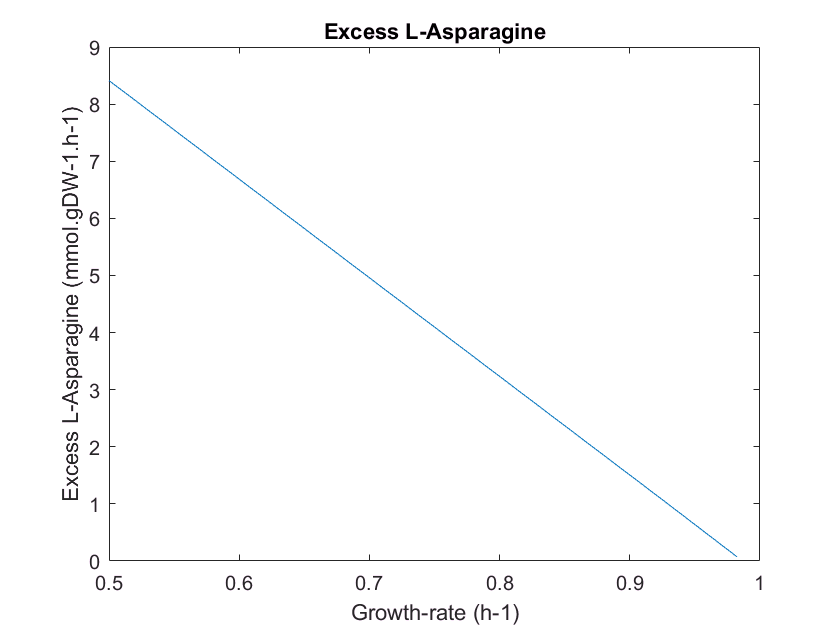

[tmp,Asparagine_MAX_rxnID] = ismember({'DM_asn__L_c'},model.rxns);
model = changeObjective(model,'DM_asn__L_c'); % Set the objective function
FBAsolution_Asparagine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessAsparagine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Asparagine = optimizeCbModel(model,'max'); % Perform FBA
    excessAsparagine(i) = FBAsolution_Asparagine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessAsparagine)
title('Excess L-Asparagine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Asparagine (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of L-asparagine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-asparagine increases the growth-rate will need to decrease. In this figure we can see that the excess L-asparagine flux can increase from 0.07233 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 8.412 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-asparagine flux beyond these levels will require using the pathways that allow for the transport of L-asparagine from the extracellular media. 

## 5. Aerobic vs Anaerobic Amino Acid Production

Now let's look at the total amount of flux that is created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

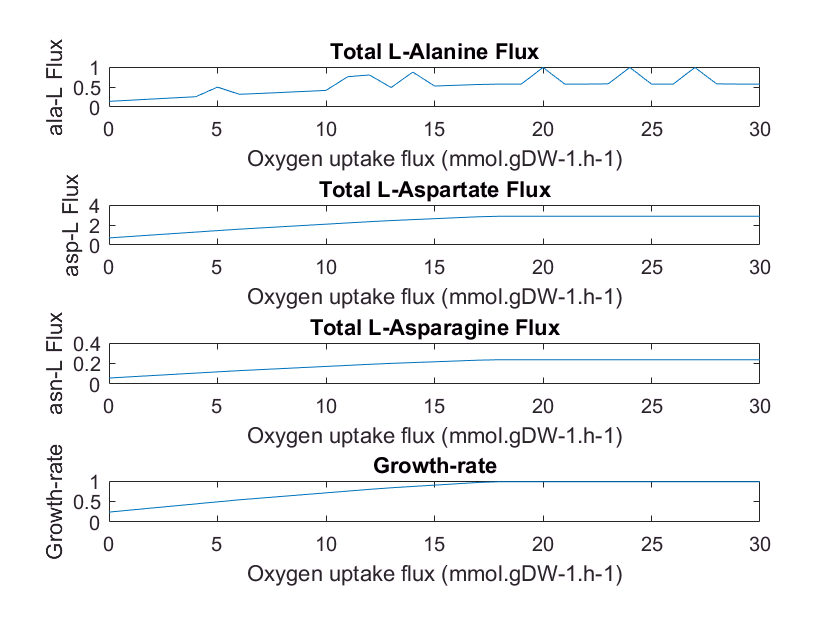

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
ala_flux = [];
asp_flux = [];
asn_flux = [];
for k = 1:31
    model = changeRxnBounds(model,'EX_o2_e',-(k-1),'b'); % Set oxygen uptake
    FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
    [P, C, vP, vC] = computeFluxSplits(model, {'ala__L_c'}, FBAsolution.x);
    ala_flux(k) = sum(vP);
    [P, C, vP, vC] = computeFluxSplits(model, {'asp__L_c'}, FBAsolution.x);
    asp_flux(k) = sum(vP);
    [P, C, vP, vC] = computeFluxSplits(model, {'asn__L_c'}, FBAsolution.x);
    asn_flux(k) = sum(vP);    
    growthRate(k) = FBAsolution.f;
end

figure(1)
oFlux = 0:30;
ax1 = subplot(4,1,1); % top subplot
ax2 = subplot(4,1,2); % middle subplot
ax3 = subplot(4,1,3); % bottom subplot
ax4 = subplot(4,1,4); % bottom subplot

plot(ax1,oFlux,ala_flux)
title(ax1,'Total L-Alanine Flux'); 
xlabel(ax1,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax1,'ala-L Flux');

plot(ax2,oFlux,asp_flux);
title(ax2,'Total L-Aspartate Flux'); 
xlabel(ax2,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax2,'asp-L Flux'); 

plot(ax3,oFlux,asn_flux);
title(ax3,'Total L-Asparagine Flux'); 
xlabel(ax3,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax3,'asn-L Flux'); 

plot(ax4,oFlux,growthRate);
title(ax4,'Growth-rate'); 
xlabel(ax4,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax4,'Growth-rate'); 

**Figure 9.** A plot showing the total amount of flux that is can be created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

Note that the noise on the L-alanine chart is the result of loops in the production pathways. 

## 6. Conclusion

The purpose of this tutorial was to identify and review the structure and capabilities of the "Alanine and Aspartate Metabolism" subsystem of the *E.coli* iJO1366 model. It began with an overview of the complete subsystem. This was followed by more detailed descritpions of the individaul L-alanine, L-aspartate and L-asparagine biosynthesis pathways. It concluded with a simulation showing the maximum flux that each these amino acids can produce in a range from anaerobic to aerobic conditions.

## References

- Palsson, B. (2015). Systems biology : constraint-based reconstruction and analysis. Cambridge, United Kingdom, Cambridge University Press.

- Palsson, B. (2006). Systems biology : properties of reconstructed networks. Cambridge ; New York, Cambridge University Press.

- Zachary A. King, Andreas Dräger, Ali Ebrahim, Nikolaus Sonnenschein, Nathan E. Lewis, and Bernhard O. Palsson (2015) *Escher: A web application for building, sharing, and embedding data-rich visualizations of biological pathways*, PLOS Computational Biology 11(8):